%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% generate AutocorrelationFunction instance and confirm properties
autocorrelation_function = AutocorrelationFunction(audio_file_manipulator.signal);
autocorrelation_function.calculate_autocorrelation_with_fourier();
autocorrelation_function.display_properties();

--------------------------------------------
--------- Auto correlation function --------
signal size : (17500, 1)
autocorrelation size : (17500, 1)
power_spectrum size : (65536, 1)
fft_point : 65536 [point]
--------------------------------------------



%% generate PartialAutocorrelationCoefficient instance and confirm properties
partial_autocorrelation_coefficient = PartialAutocorrelationCoefficient(autocorrelation_function.autocorrelation);
partial_autocorrelation_coefficient.display_properties();

----------------------------------------------
----- Partial AutoCorrelation Coefficient ----
autocorrelation size : (17500, 1)
order : 30
linear_predictive_coefficient size : (1, 31)
partial_autocorelation_coefficient size : (1, 31)
numerators size : (1, 31)
denominators size : (1, 31)
----------------------------------------------



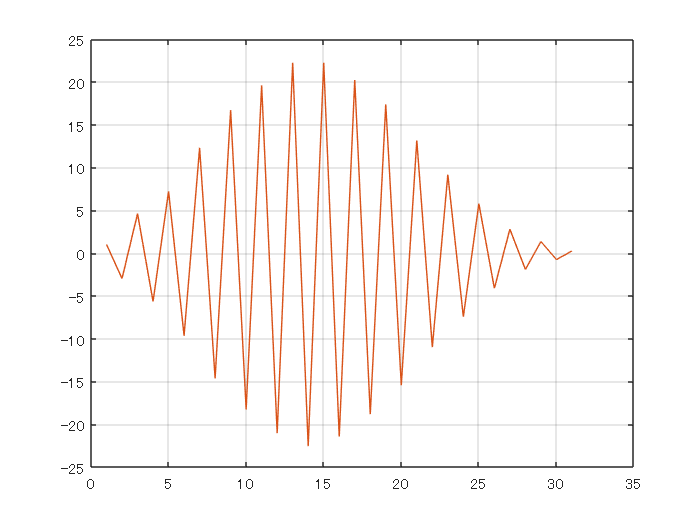

dimension = 30;
alpha = levinson(autocorrelation_function.autocorrelation, dimension);
plot(alpha);
hold on;
grid on;
plot(partial_autocorrelation_coefficient.linear_predictive_coefficient);